# RAMPKAR PAPER - R2H, R2P xcorr

## Loading the data

% Figure 2 - Cross-correlation RAMPKAR2-HYlight and RAMPKAR2-Perceval

% basic paths
addpath('\\albecklab.mcb.ucdavis.edu\data\Code\DatalocHandler\', ...
    '\\albecklab.mcb.ucdavis.edu\data\Code\Image Analysis\', ...
    '\\albecklab.mcb.ucdavis.edu\data\Code\Cell Trace\')

iBasePath = '\\albecklab.mcb.ucdavis.edu\data\imageData\RAMPKAR\';
pBasePath = '\\albecklab.mcb.ucdavis.edu\data\Processed Data\RAMPKAR\';

%% Load the data for RAMPKAR-HYlight for crosscorr

% List of replicate subpaths (relative to pBasePath)
replicatePaths = {
    '2023-09-26 10A RAMPKAR2 HYLIGHT\2023-09-26 10A RAMPKAR2 HYLIGHT_Processed.mat' % has MTK + oligo  treatment
    '2023-09-25 10A RAMPKAR2 HYLIGHT\2023-09-25 10A RAMPKAR2 HYLIGHT_Processed.mat' % has MTK + oligo  treatment
    '2025-06-10_MCF10A_R2HmO_R2P\2025-06-10_MCF10A_R2HmO_R2P_Processed.mat'% has MTK + oligo  treatment
    '2025-05-22_MCF10A_R2HmO_R2P\2025-05-22_MCF10A_R2HmO_R2P_Processed.mat' % this one is behaving very weirdly (vehicle) after Perceval pwrat
    '2025-05-14_MCF10A_R2HmO_R2P\2025-05-14_MCF10A_R2HmO_R2P_Processed.mat'}; 

% Preallocate
f2Data = cell(1, numel(replicatePaths));

% Load in a loop
for i = 1:numel(replicatePaths)
    f2D = load([pBasePath, replicatePaths{i}]);
    f2Data{i} = f2D.dataloc;
end

## Figuring out the optimal lag per sensor combination

Load the data from the pulse analysis that was performed in each Fullproc script of each experiment. They can be found on the server in imageData/experiementName/

%% Get pulses and subset the data, look at the lag values
%% Loop for Replicates 1–2 (Markhus')

for i = 1:2
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 3,'tmaxaftertx', 12, ...
        'crosscorr', {'HYLIGHT_RAMPKAR2'}, ...
        'exclude', {'IPA','TwoDG'});
    
    deltaR2_HY.Tx(deltaR2_HY.Tx == "1 INSIM") = "Vehicle";
    deltaR2_HY.Tx = regexprep(deltaR2_HY.Tx, '10\s*uM\s*MK8722\s*\+\s*3\s*uM\s*Oligo', '3uM Oligo + 10uM MK8722');
    deltaR2_HY.PtxTx = regexprep(deltaR2_HY.PtxTx, '10\s*uM\s*MK8722\s*\+\s*3\s*uM\s*Oligo', '3uM Oligo + 10uM MK8722');
    deltaR2all_HY{i} = deltaR2_HY;
    clear deltaR2_HY
end

%% Loop for Replicates 3–5 (Marion's)

for i = 3:5
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 5,'tmaxaftertx', 12, ...
        'crosscorr', {'HYLIGHT_RAMPKAR2'});
    deltaR2all_HY{i} = deltaR2_HY;
    clear deltaR2_HY
end


for i = 3:5 
    deltaR2_Per = convertPulseToDataframe(f2Data{i}, {'PERCEVAL','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 5, ...
        'crosscorr', {'PERCEVAL_RAMPKAR2'}, ...
        'tmaxaftertx', 12);
    deltaR2all_Per{i} = deltaR2_Per;
    clear deltaR2_Per

end

%% Pool data
% Concatenate the replicates
dataH = vertcat(deltaR2all_HY{:});
dataP = vertcat(deltaR2all_Per{:});

### Explore with some stats

#### Mean/median xcorr per Pre-treatment + Treatment of highly correlated cells

hCorr = dataP(abs(dataP.PERCEVAL_RAMPKAR2_maxXcorr)>0.5,:);
highCorrs = grpstats(hCorr,'PtxTx',["mean","median","sem"],"DataVars",["PERCEVAL_RAMPKAR2_maxXcorrLagInMin","PERCEVAL_RAMPKAR2_maxXcorr"])

highCorrs = 27×8 table
                                                           PtxTx                    GroupCount    mean_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    median_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    sem_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    mean_PERCEVAL_RAMPKAR2_maxXcorr    median_PERCEVAL_RAMPKAR2_maxXcorr    sem_PERCEVAL_RAMPKAR2_maxXcorr
                                           _____________________________________    __________    _______________________________________    _________________________________________    ______________________________________    _______________________________    _________________________________    ______________________________

    0mM GlucNoIns + 1 Vehicle     

hCorr = dataH(abs(dataH.HYLIGHT_RAMPKAR2_maxXcorr)>0.5,:);
highCorrs = grpstats(hCorr,'PtxTx',["mean","median","sem"],"DataVars",["HYLIGHT_RAMPKAR2_maxXcorrLagInMin","HYLIGHT_RAMPKAR2_maxXcorr"])

highCorrs = 31×8 table
                                                                    PtxTx                       GroupCount    mean_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    median_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    sem_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    mean_HYLIGHT_RAMPKAR2_maxXcorr    median_HYLIGHT_RAMPKAR2_maxXcorr    sem_HYLIGHT_RAMPKAR2_maxXcorr
                                                 ___________________________________________    __________    ______________________________________    ________________________________________    _____________________________________    ______________________________    ________________________________    _____________________________

    17mM Gluc + 1 Vehi

Interestingly, median of 2 oligo conditions shows favorable negative lag instead of 0 min.

#### Mean/median xcorr per Pre-treatment 

hCorr = dataP(abs(dataP.PERCEVAL_RAMPKAR2_maxXcorr)>0.5,:);
highCorrs = grpstats(hCorr,'Ptx',["mean","median","sem"],"DataVars",["PERCEVAL_RAMPKAR2_maxXcorrLagInMin","PERCEVAL_RAMPKAR2_maxXcorr"])

highCorrs = 5×8 table
                              Ptx           GroupCount    mean_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    median_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    sem_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    mean_PERCEVAL_RAMPKAR2_maxXcorr    median_PERCEVAL_RAMPKAR2_maxXcorr    sem_PERCEVAL_RAMPKAR2_maxXcorr
                       _________________    __________    _______________________________________    _________________________________________    ______________________________________    _______________________________    _________________________________    ______________________________

    0mM GlucNoIns      "0mM GlucNoIns"          882                         -1.585                        

hCorr = dataH(abs(dataH.HYLIGHT_RAMPKAR2_maxXcorr)>0.5,:);
highCorrs = grpstats(hCorr,'Ptx',["mean","median","sem"],"DataVars",["HYLIGHT_RAMPKAR2_maxXcorrLagInMin","HYLIGHT_RAMPKAR2_maxXcorr"])

highCorrs = 5×8 table
                              Ptx           GroupCount    mean_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    median_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    sem_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    mean_HYLIGHT_RAMPKAR2_maxXcorr    median_HYLIGHT_RAMPKAR2_maxXcorr    sem_HYLIGHT_RAMPKAR2_maxXcorr
                       _________________    __________    ______________________________________    ________________________________________    _____________________________________    ______________________________    ________________________________    _____________________________

    17mM Gluc          "17mM Gluc"            11991                       4.2907                                      

#### Mean/median xcorr per Treatment 

hCorr = dataP(abs(dataP.PERCEVAL_RAMPKAR2_maxXcorr)>0.5,:);
highCorrs = grpstats(hCorr,'Tx',["mean","median","sem"],"DataVars",["PERCEVAL_RAMPKAR2_maxXcorrLagInMin","PERCEVAL_RAMPKAR2_maxXcorr"])

highCorrs = 7×8 table
                                          Tx                GroupCount    mean_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    median_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    sem_PERCEVAL_RAMPKAR2_maxXcorrLagInMin    mean_PERCEVAL_RAMPKAR2_maxXcorr    median_PERCEVAL_RAMPKAR2_maxXcorr    sem_PERCEVAL_RAMPKAR2_maxXcorr
                               _________________________    __________    _______________________________________    _________________________________________    ______________________________________    _______________________________    _________________________________    ______________________________

    1 Vehicle                  "1 Vehicle"                     1179       

hCorr = dataH(abs(dataH.HYLIGHT_RAMPKAR2_maxXcorr)>0.5,:);
highCorrs = grpstats(hCorr,'Tx',["mean","median","sem"],"DataVars",["HYLIGHT_RAMPKAR2_maxXcorrLagInMin","HYLIGHT_RAMPKAR2_maxXcorr"])

highCorrs = 9×8 table
                                            Tx                GroupCount    mean_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    median_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    sem_HYLIGHT_RAMPKAR2_maxXcorrLagInMin    mean_HYLIGHT_RAMPKAR2_maxXcorr    median_HYLIGHT_RAMPKAR2_maxXcorr    sem_HYLIGHT_RAMPKAR2_maxXcorr
                                __________________________    __________    ______________________________________    ________________________________________    _____________________________________    ______________________________    ________________________________    _____________________________

    1 Vehicle                   "1 Vehicle"                      6080             

#### Facetted boxplots of max xcorr for cells (all, no high xcorr filtering)

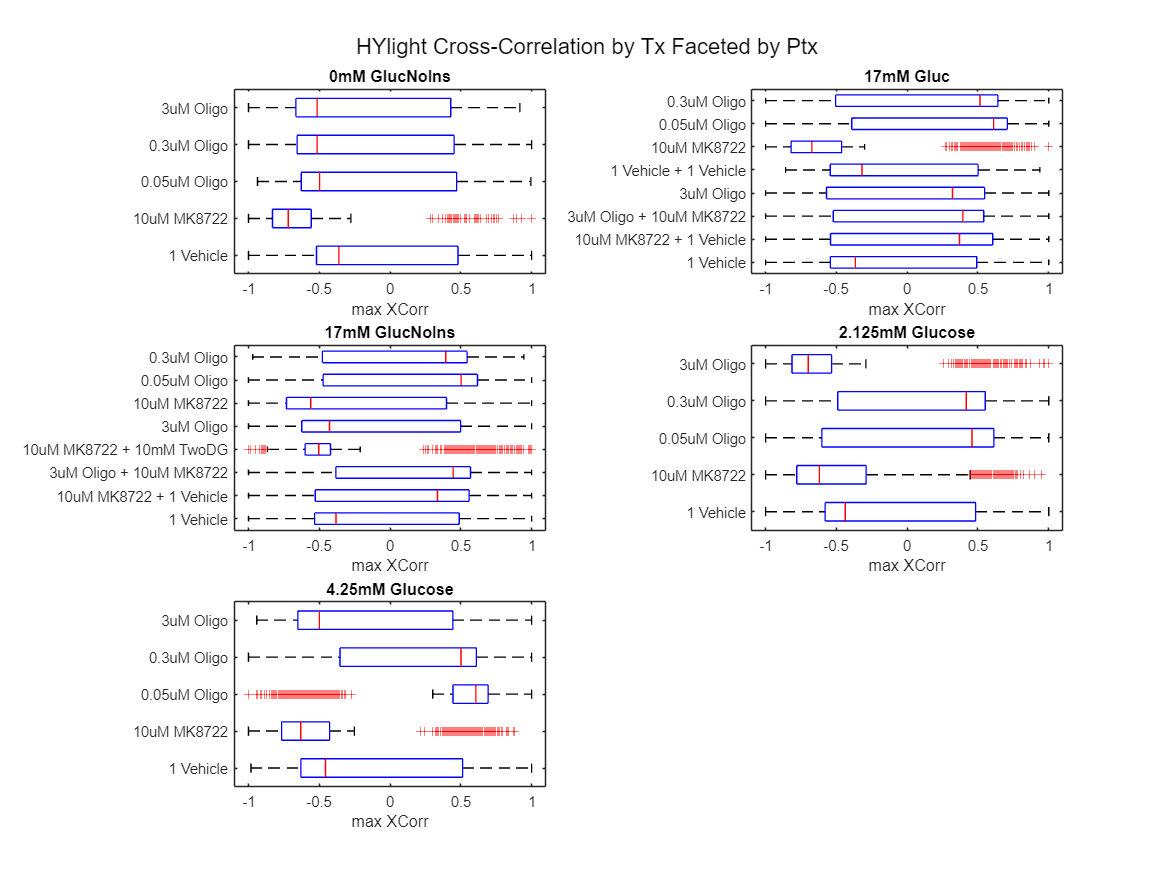

% Get unique pre-treatments
pretreatments = unique(dataH.Ptx);

% Prepare figure
figure('Renderer', 'painters', 'Position', [10 10 1200 900]);
numPtx = numel(pretreatments);
rows = ceil(sqrt(numPtx));
cols = ceil(numPtx / rows);

for i = 1:numPtx
    subplot(rows, cols, i);
    
    % Subset data for current Ptx
    subData = dataH(strcmp(dataH.Ptx, pretreatments{i}), :);
    
    % Boxplot grouped by Tx
    boxplot(subData.HYLIGHT_RAMPKAR2_maxXcorr, subData.Tx, 'Orientation', 'horizontal');
    title(sprintf('%s', pretreatments{i}), 'Interpreter', 'none');
    xlabel('max XCorr');
    set(gca, 'FontSize', 10);
end

sgtitle('HYlight Cross-Correlation by Tx Faceted by Ptx');

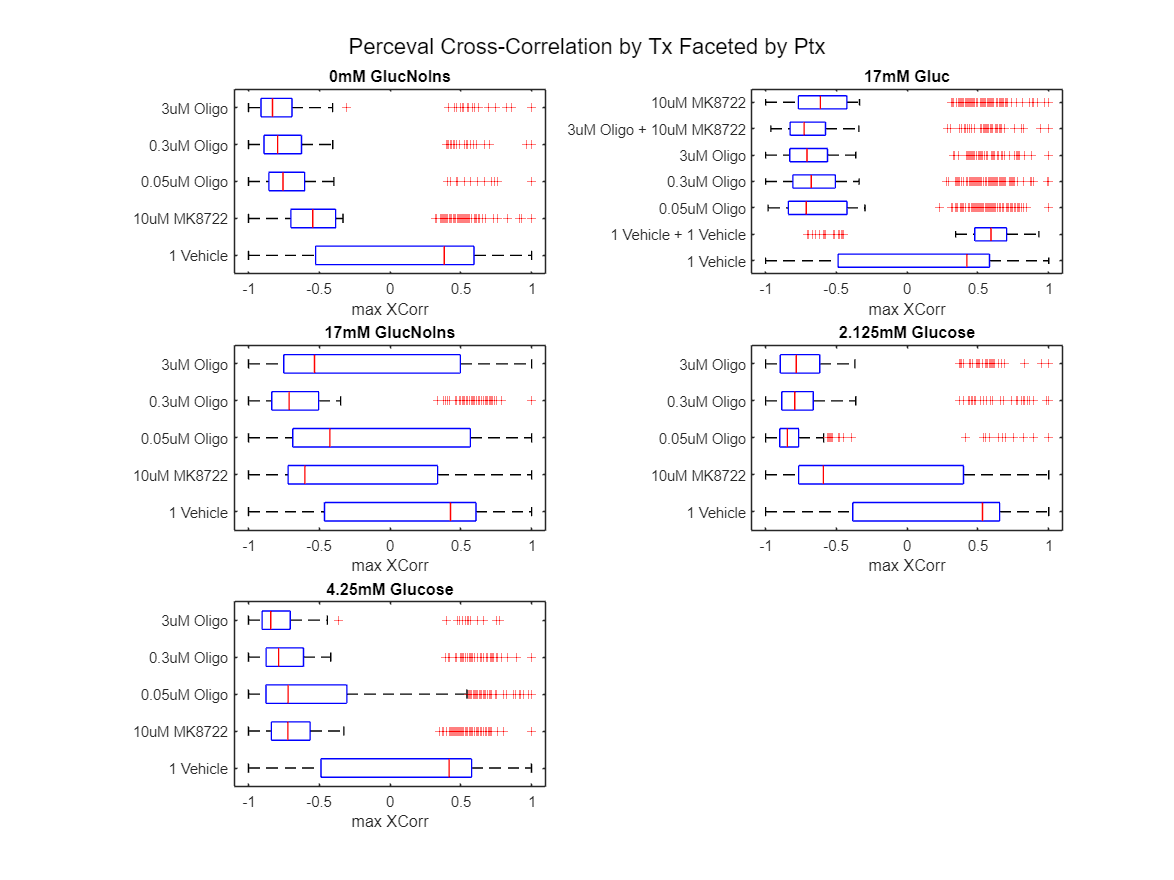

% Get unique pre-treatments
pretreatments = unique(dataP.Ptx);

% Prepare figure
figure('Renderer', 'painters', 'Position', [10 10 1200 900]);
numPtx = numel(pretreatments);
rows = ceil(sqrt(numPtx));
cols = ceil(numPtx / rows);

for i = 1:numPtx
    subplot(rows, cols, i);
    
    % Subset data for current Ptx
    subData = dataP(strcmp(dataP.Ptx, pretreatments{i}), :);
    
    % Boxplot grouped by Tx
    boxplot(subData.PERCEVAL_RAMPKAR2_maxXcorr, subData.Tx, 'Orientation', 'horizontal');
    title(sprintf('%s', pretreatments{i}), 'Interpreter', 'none');
    xlabel('max XCorr');
    set(gca, 'FontSize', 10);
end

sgtitle('Perceval Cross-Correlation by Tx Faceted by Ptx');

### Plot the distributions of xcorr and xcorr optimal lag

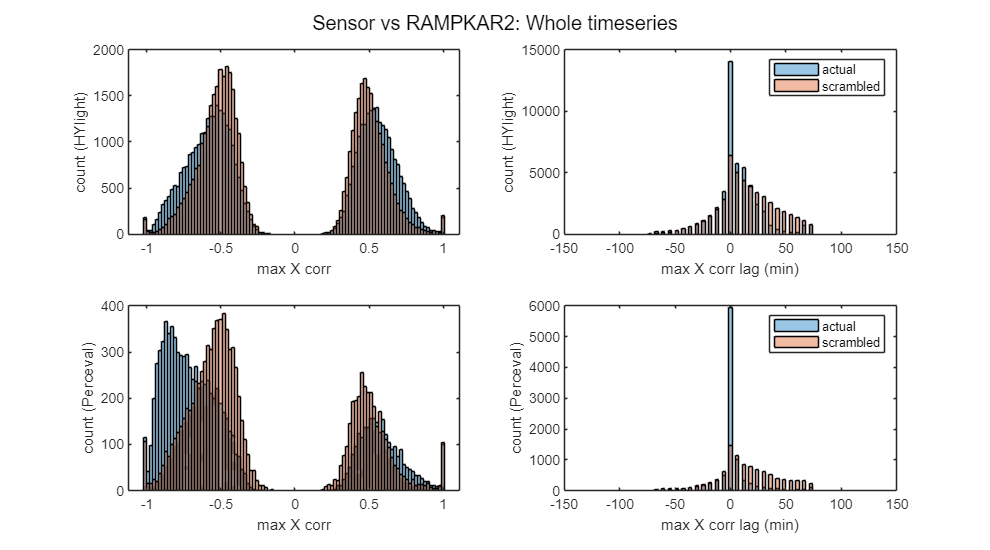

%% Check out the distribution of x_corr values and lags in all conditions
% HYLIGHT vs RAMPKAR2
binRange = [-150, 150];
edges = linspace(binRange(1), binRange(2), 100); % 100 bins means 51 edges

figure('Renderer', 'painters', 'Position', [10 10 900 500]);
subplot(2,2,1)
histogram(dataH.HYLIGHT_RAMPKAR2_maxXcorr,100, Normalization='count');
hold on;
histogram(dataH.HYLIGHT_Scrambled_RAMPKAR2_maxXcorr,100, Normalization='count');
alpha(.4);
xlabel('max X corr');
ylabel('count (HYlight)');
subplot(2,2,2)
histogram(dataH.HYLIGHT_RAMPKAR2_maxXcorrLagInMin,edges, Normalization='count');
hold on;
histogram(dataH.HYLIGHT_Scrambled_RAMPKAR2_maxXcorrLagInMin,edges, Normalization='count');
alpha(.4);
xlim([-150 150]);
xlabel('max X corr lag (min)');
ylabel('count (HYlight)');
legend('actual','scrambled')

% Perceval vs RAMPKAR2

subplot(2,2,3)
histogram(dataP.PERCEVAL_RAMPKAR2_maxXcorr,100, Normalization='count');
hold on;
histogram(dataP.PERCEVAL_Scrambled_RAMPKAR2_maxXcorr,100, Normalization='count');
alpha(.4);
xlabel('max X corr');
ylabel('count (Perceval)')

subplot(2,2,4)
histogram(dataP.PERCEVAL_RAMPKAR2_maxXcorrLagInMin, edges, Normalization='count');
hold on;
histogram(dataP.PERCEVAL_Scrambled_RAMPKAR2_maxXcorrLagInMin, edges, Normalization='count');
alpha(.4);
xlim([-150 150]);
xlabel('max X corr lag (min)');
ylabel('count (Perceval)');
legend('actual','scrambled')
sgtitle('Sensor vs RAMPKAR2: Whole timeseries');

Ok optimal lag is at 0 min for both Perceval and HYlight it seems.

## Force a 0 minute lag for both HYlight and Perceval vs RAMPKAR2

%% Force a lag of 0 minutes for Hylight
% Markhus' datasets
for i = 1:2
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 3, ...
        'crosscorr', {'HYLIGHT_RAMPKAR2'}, ...
        'exclude', {'IPA','TwoDG'}, ...
        'tmaxaftertx', 12, 'forcecorrlag',0);

    deltaR2_HY.Tx(deltaR2_HY.Tx == "1 INSIM") = "1 Vehicle";
    deltaR2_HY.Tx = regexprep(deltaR2_HY.Tx, '10\s*uM\s*MK8722\s*\+\s*3\s*uM\s*Oligo', '3uM Oligo + 10uM MK8722');
    deltaR2_HY.PtxTx = regexprep(deltaR2_HY.PtxTx, '10\s*uM\s*MK8722\s*\+\s*3\s*uM\s*Oligo', '3uM Oligo + 10uM MK8722');
    deltaR2all_HY{i} = deltaR2_HY;
    clear deltaR2_HY 

end


% My datasets, which treatments to keep in subset of data

for i = 3:5
    deltaR2_HY = convertPulseToDataframe(f2Data{i}, {'HYLIGHT','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 5, ...
        'crosscorr', {'HYLIGHT_RAMPKAR2'}, ...
        'tmaxaftertx', 12, 'forcecorrlag',0);
    % Store results
    deltaR2all_HY{i} = deltaR2_HY;
    clear deltaR2_HY 

end


for i = 3:5 
    deltaR2_Per = convertPulseToDataframe(f2Data{i}, {'PERCEVAL','RAMPKAR2'}, ...
        'pulsepars', {'Delta_Mean','Mean_Before'}, ...
        'aftertx', 1, 'tmaxback', 5, ...
        'crosscorr', {'PERCEVAL_RAMPKAR2'}, ...
        'tmaxaftertx', 12, 'forcecorrlag',0);
    deltaR2all_Per{i} = deltaR2_Per;
    clear deltaR2_Per 

end

%% Pool data
% Concatenate the replicates
dataHlag = vertcat(deltaR2all_HY{:});
dataPlag = vertcat(deltaR2all_Per{:});

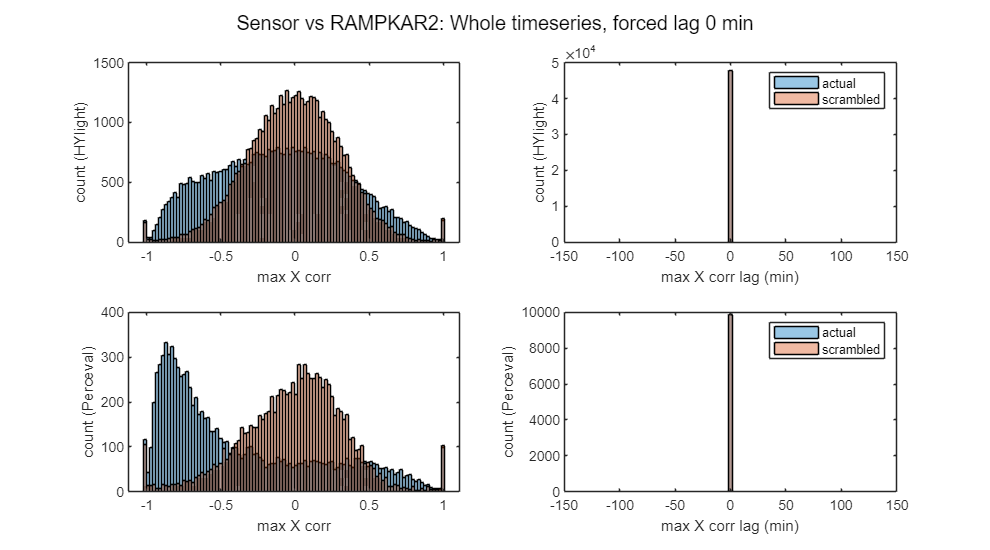

%% Plot histograms again

% HYLIGHT vs RAMPKAR2

binRange = [-150, 150];
edges = linspace(binRange(1), binRange(2), 100); % 100 bins means 51 edges

figure('Renderer', 'painters', 'Position', [10 10 900 500]);
subplot(2,2,1)
histogram(dataHlag.HYLIGHT_RAMPKAR2_maxXcorr,100, Normalization='count');
hold on;
histogram(dataHlag.HYLIGHT_Scrambled_RAMPKAR2_maxXcorr,100, Normalization='count');
alpha(.4);
xlabel('max X corr');
ylabel('count (HYlight)');
subplot(2,2,2)
histogram(dataHlag.HYLIGHT_RAMPKAR2_maxXcorrLagInMin,edges, Normalization='count');
hold on;
histogram(dataHlag.HYLIGHT_Scrambled_RAMPKAR2_maxXcorrLagInMin,edges, Normalization='count');
alpha(.4);
xlim([-150 150]);
xlabel('max X corr lag (min)');
ylabel('count (HYlight)');
legend('actual','scrambled')

% Perceval vs RAMPKAR2

subplot(2,2,3)
histogram(dataPlag.PERCEVAL_RAMPKAR2_maxXcorr,100, Normalization='count');
hold on;
histogram(dataPlag.PERCEVAL_Scrambled_RAMPKAR2_maxXcorr,100, Normalization='count');
alpha(.4);
xlabel('max X corr');
ylabel('count (Perceval)')

subplot(2,2,4)
histogram(dataPlag.PERCEVAL_RAMPKAR2_maxXcorrLagInMin, edges, Normalization='count');
hold on;
histogram(dataPlag.PERCEVAL_Scrambled_RAMPKAR2_maxXcorrLagInMin, edges, Normalization='count');
alpha(.4);
xlim([-150 150]);
xlabel('max X corr lag (min)');
ylabel('count (Perceval)');
legend('actual','scrambled')
sgtitle('Sensor vs RAMPKAR2: Whole timeseries, forced lag 0 min');

#### Facetted boxplots of max xcorr for cells (all, no high xcorr filtering, with lag)

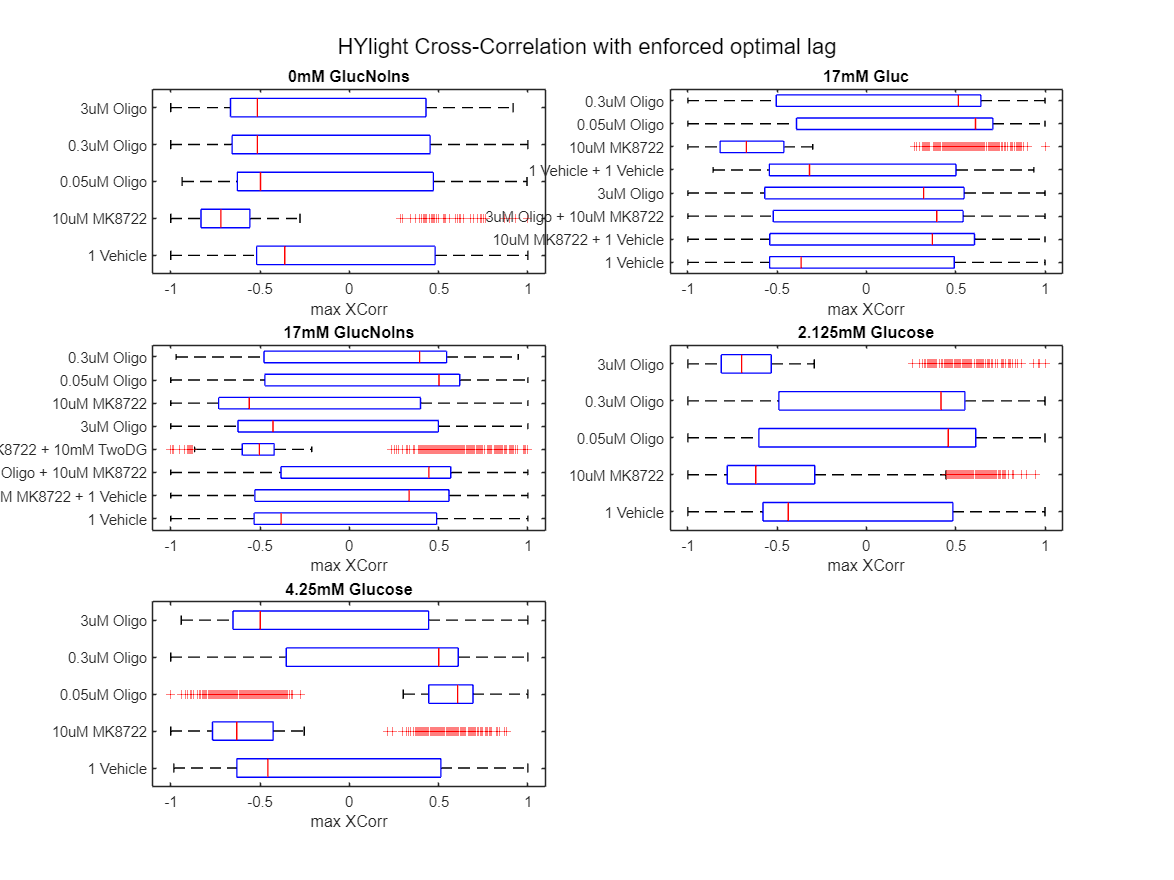

% Get unique pre-treatments
pretreatments = unique(dataHlag.Ptx);

% Prepare figure
figure('Renderer', 'painters', 'Position', [10 10 1200 900]);
numPtx = numel(pretreatments);
rows = ceil(sqrt(numPtx));
cols = ceil(numPtx / rows);

for i = 1:numPtx
    subplot(rows, cols, i);
    
    % Subset data for current Ptx
    subData = dataHlag(strcmp(dataHlag.Ptx, pretreatments{i}), :);
    
    % Boxplot grouped by Tx
    boxplot(subData.HYLIGHT_RAMPKAR2_maxXcorr, subData.Tx, 'Orientation', 'horizontal');
    title(sprintf('%s', pretreatments{i}), 'Interpreter', 'none');
    xlabel('max XCorr');
    set(gca, 'FontSize', 10);
end

sgtitle('HYlight Cross-Correlation with enforced optimal lag');

## Corr baseline behavior to post-treatment heterogeneous responses (RAMPKAR2 and HYlight)

Compare :

- Pre-oligo HYlight area under the curve (should capture the range of baseline but would it clearly distinguish high baseline from oscillatory?)

- Pre-oligo RAMPKAR2 AUC

Divide those into categories such as high, medium, low and oscillatory?

to 

- Post oligo HYlight time to first peak, slope of first peak, number of peaks, amp of peak1 vs peak2 and maybe other parameters

- Post oligo RAMPKAR2 parameters

### Group/Classify baseline behavior

I'm only gonna use my HYlight-RAMPKAR2 cells I think.

%% Violin plots of correlation at optimal lag, for all conditions, colored by glucose concentration ?
% High, medium, low and oscillatory?
tabulate(dataHlag.Tx)

                     Value    Count   Percent
                 1 Vehicle    16662     23.40%
   10uM MK8722 + 1 Vehicle     9255     13.00%
   3uM Oligo + 10uM MK8722     7608     10.69%
                 3uM Oligo    11734     16.48%
  10uM MK8722 + 10mM TwoDG     3622      5.09%
     1 Vehicle + 1 Vehicle      235      0.33%
               10uM MK8722     6590      9.26%
              0.05uM Oligo     8536     11.99%
               0.3uM Oligo     6953      9.77%


tabulate(dataPlag.Tx)

                    Value    Count   Percent
                1 Vehicle     2689     18.64%
    1 Vehicle + 1 Vehicle      159      1.10%
              10uM MK8722     3917     27.16%
             0.05uM Oligo     2142     14.85%
              0.3uM Oligo     2750     19.07%
                3uM Oligo     2140     14.84%
  3uM Oligo + 10uM MK8722      626      4.34%


## Explore MK8722 effect on xcorr between HYlight/Perceval and RAMPKAR2

%% Violin plots of correlation at optimal lag

dataHsub = dataHlag(matches(dataHlag.Ptx, {'17mM Gluc'}) & matches(dataHlag.Tx, ...
        {'1 Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'}), :);
dataPsub = dataPlag(matches(dataPlag.Ptx, {'17mM Gluc'}) & matches(dataPlag.Tx, ...
        {'1 Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'}), :);

% clean up legend
dataHsub.Tx(dataHsub.Tx == "1 Vehicle 1 Vehicle") = "Vehicle";
dataHsub.Tx(dataHsub.Tx == "1 Vehicle") = "Vehicle";
dataPsub.Tx(dataPsub.Tx == "1 Vehicle") = "Vehicle";
%order
dataHsub.Tx = categorical(dataHsub.Tx,{'Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'});
dataPsub.Tx = categorical(dataPsub.Tx,{'Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'});


tabulate(dataHsub.tx);

                    Value    Count   Percent
                  Vehicle     6128     41.96%
                3uM Oligo     4293     29.40%
  3uM Oligo + 10uM MK8722     4182     28.64%


tabulate(dataPsub.Tx);

                    Value    Count   Percent
                  Vehicle      851     41.07%
                3uM Oligo      595     28.72%
  3uM Oligo + 10uM MK8722      626     30.21%


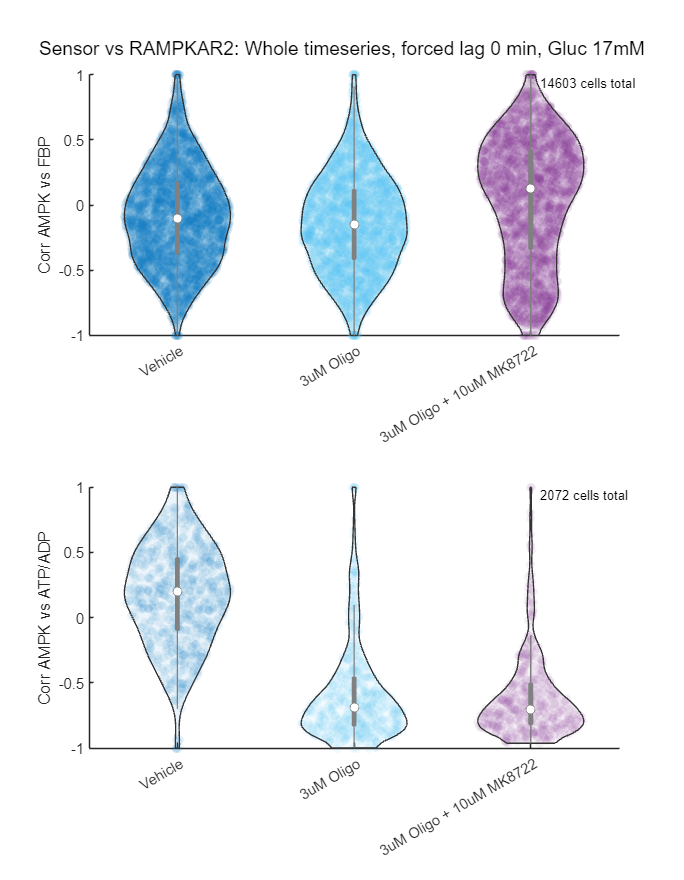

%% Plot

figure('Renderer', 'painters', 'Position', [10 10 700 900]);
subplot(2,1,1);
violinplot(dataHsub.HYLIGHT_RAMPKAR2_maxXcorr,dataHsub.Tx,'ShowData',true,'ViolinAlpha',0.08, 'EdgeColor',[0.2,0.2,0.2]);
ylim([-1,1]); ylabel('Corr AMPK vs FBP')
nCellsH = numel(dataHsub.cellID);
text(0.85, 1, sprintf('%d cells total', nCellsH), 'Units','normalized', 'FontSize',9, 'VerticalAlignment','top');
subplot(2,1,2);
violinplot(dataPsub.PERCEVAL_RAMPKAR2_maxXcorr,dataPsub.Tx,'ShowData',true,'ViolinAlpha',0.08, 'EdgeColor',[0.2,0.2,0.2]);
ylim([-1,1]); ylabel('Corr AMPK vs ATP/ADP')
nCellsH = numel(dataPsub.cellID);
text(0.85, 1, sprintf('%d cells total', nCellsH), 'Units','normalized', 'FontSize',9, 'VerticalAlignment','top');
sgtitle('Sensor vs RAMPKAR2: Whole timeseries, forced lag 0 min, Gluc 17mM')

Note that the weird Perceval vehicle distribution may be caused by the wonky data in the 2025-05-14 vehicles which are being reprocessed 7/17/25

Note that the Perceval data is missing one whole replicate

### HYlight treatments vs vehicle

%% compare the correlations to see if they are significantly different than vehicle
[~,~,statsCorr] = anova1(dataHsub.HYLIGHT_RAMPKAR2_maxXcorr,dataHsub.Tx,'off');
[resultsCorr,~,~,gnamesCorr] = multcompare(statsCorr,"CriticalValueType","dunnett",'ControlGroup',find(matches(statsCorr.gnames,'Vehicle')),'Display','off','Approximate',false); 
HYLIGHT_RAMPKAR2_Xcorr = array2table(resultsCorr,"VariableNames", ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
HYLIGHT_RAMPKAR2_Xcorr.("Group") = gnamesCorr(HYLIGHT_RAMPKAR2_Xcorr.("Group"));
HYLIGHT_RAMPKAR2_Xcorr.("Control Group") = gnamesCorr(HYLIGHT_RAMPKAR2_Xcorr.("Control Group"))

HYLIGHT_RAMPKAR2_Xcorr = 2×6 table
               Group               Control Group    Lower Limit    Difference    Upper Limit     P-value  
    ___________________________    _____________    ___________    __________    ___________    __________

    {'3uM Oligo'              }     {'Vehicle'}      -0.077104     -0.055127      -0.03315      5.4236e-08
    {'3uM Oligo + 10uM MK8722'}     {'Vehicle'}        0.10264       0.12476       0.14688      8.8818e-16


### Perceval treatments vs vehicle

%% compare the correlations to see if they are significantly different than vehicle
[~,~,statsCorr] = anova1(dataPsub.PERCEVAL_RAMPKAR2_maxXcorr,dataPsub.Tx,'off');
[resultsCorr,~,~,gnamesCorr] = multcompare(statsCorr,"CriticalValueType","dunnett",'ControlGroup',find(matches(statsCorr.gnames,'Vehicle')),'Display','off','Approximate',false); 
PERCEVAL_RAMPKAR2_Xcorr = array2table(resultsCorr,"VariableNames", ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
PERCEVAL_RAMPKAR2_Xcorr.("Group") = gnamesCorr(PERCEVAL_RAMPKAR2_Xcorr.("Group"));
PERCEVAL_RAMPKAR2_Xcorr.("Control Group") = gnamesCorr(PERCEVAL_RAMPKAR2_Xcorr.("Control Group"))

PERCEVAL_RAMPKAR2_Xcorr = 2×6 table
               Group               Control Group    Lower Limit    Difference    Upper Limit     P-value  
    ___________________________    _____________    ___________    __________    ___________    __________

    {'3uM Oligo'              }     {'Vehicle'}      -0.79254       -0.74245      -0.69236      4.4409e-16
    {'3uM Oligo + 10uM MK8722'}     {'Vehicle'}      -0.82904        -0.7757      -0.72235               0


### Excluding Nick's replicates

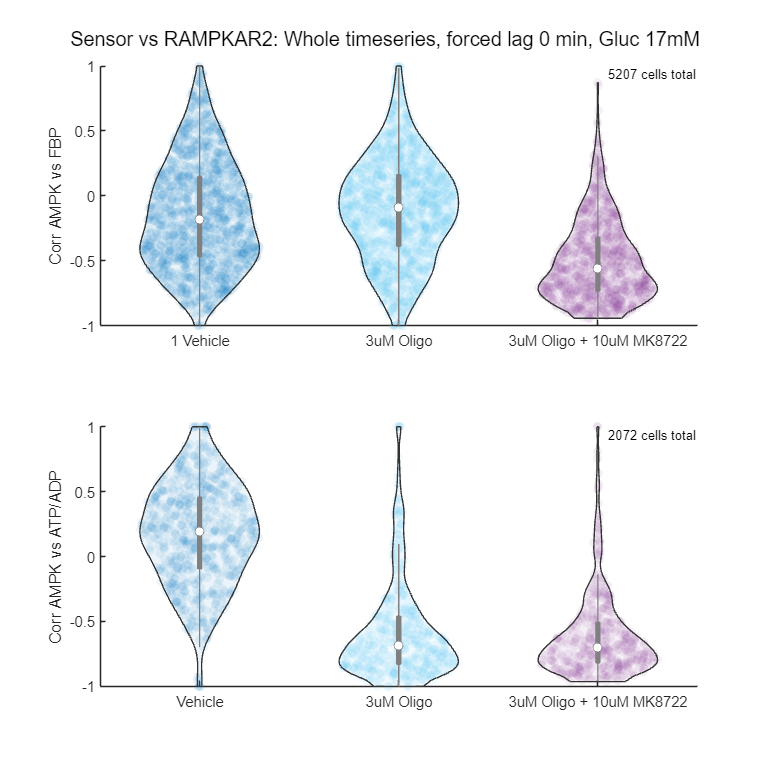

%% Plot

dataHsub = dataHlag(matches(dataHlag.Ptx, {'17mM Gluc'}) & matches(dataHlag.Tx, ...
        {'1 Vehicle','3uM Oligo','3uM Oligo + 10uM MK8722'}) & matches (dataHlag.exp,{'2025-05-14_MCF10A_R2HmO_R2P', ...
        '2025-06-10_MCF10A_R2HmO_R2P','2025-05-22_MCF10A_R2HmO_R2P'}), :);

figure('Renderer', 'painters', 'Position', [10 10 700 700]);
subplot(2,1,1);
violinplot(dataHsub.HYLIGHT_RAMPKAR2_maxXcorr,dataHsub.Tx,'ShowData',true,'ViolinAlpha',0.08, 'EdgeColor',[0.2,0.2,0.2]);
ylim([-1,1]); ylabel('Corr AMPK vs FBP')
nCellsH = numel(dataHsub.cellID);
text(0.85, 1, sprintf('%d cells total', nCellsH), 'Units','normalized', 'FontSize',9, 'VerticalAlignment','top');
subplot(2,1,2);
violinplot(dataPsub.PERCEVAL_RAMPKAR2_maxXcorr,dataPsub.Tx,'ShowData',true,'ViolinAlpha',0.08, 'EdgeColor',[0.2,0.2,0.2]);
ylim([-1,1]); ylabel('Corr AMPK vs ATP/ADP')
nCellsH = numel(dataPsub.cellID);
text(0.85, 1, sprintf('%d cells total', nCellsH), 'Units','normalized', 'FontSize',9, 'VerticalAlignment','top');
sgtitle('Sensor vs RAMPKAR2: Whole timeseries, forced lag 0 min, Gluc 17mM')